clear
addpath control_inverse_dynamics
load("trajectories.mat");
modelName = 'CONTROL_INVERSE_DYNAMICS';

load_system(modelName);
out = sim(modelName);

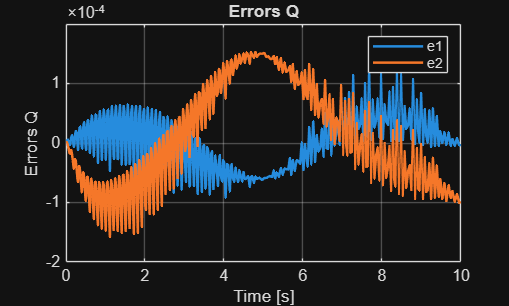

errors_Q  = out.errors_Q;
errors_dQ  = out.errors_dQ;
torque   = out.torque;

erori_Q_data = squeeze(errors_Q.Data);
erori_dQ_data = squeeze(errors_dQ.Data);
torque_data  = squeeze(torque.Data);

figure
plot(errors_Q.Time, erori_Q_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Errors Q')
title('Errors Q')
legend('e1', 'e2')

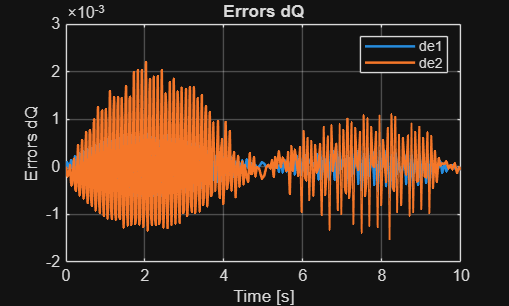


figure
plot(errors_dQ.Time, erori_dQ_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Errors dQ')
title('Errors dQ')
legend('de1', 'de2')

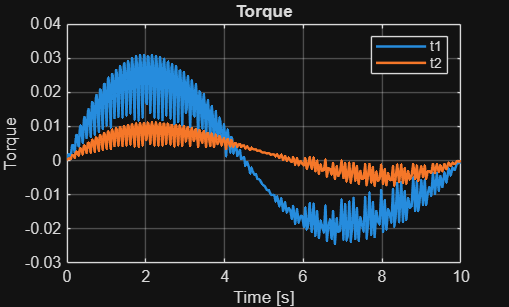


figure
plot(torque.Time, torque_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Torque')
title('Torque')
legend('t1', 't2')